# Lab 4 - Working with 'real' data

## Problem 1

clc; clear; close all;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:)

ans =    940680016         315          45          10


1) Exploration of the satellite data.

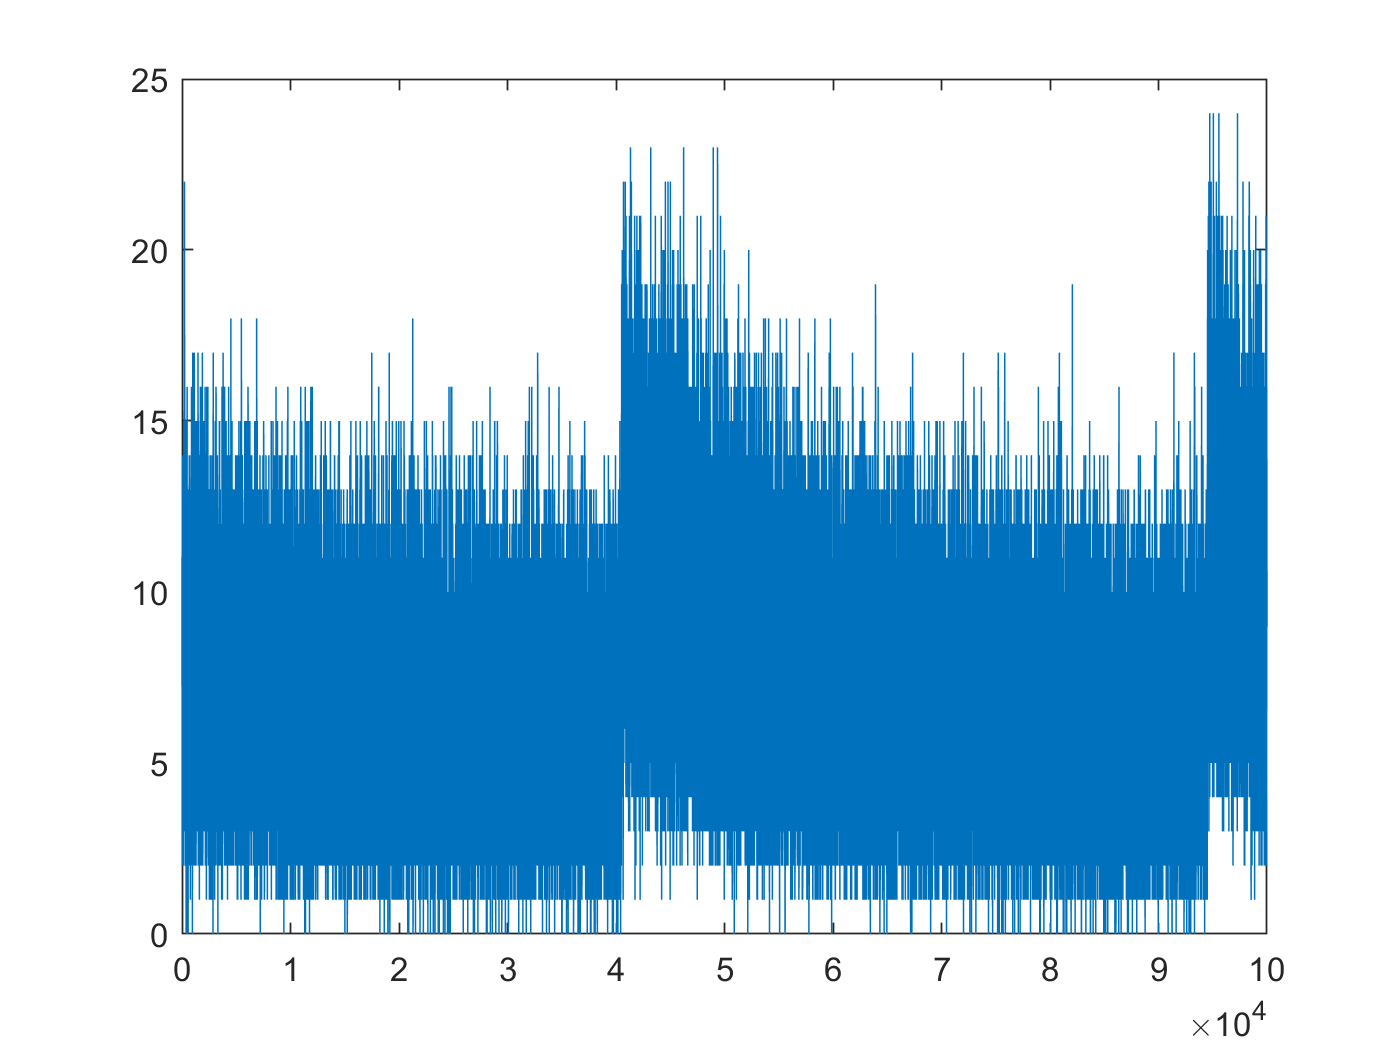

% Time (GPS seconds), Solar Phase (deg), Earth Longitude (deg), Particle Counts

% plot(mydata(:,1),mydata(:,4)); % plot is a big mess, much to large
% max(diff(mydata(:,1))) % same time interval, every 100 ms, no gaps
% max(diff(mydata(:,2))) % same
% max(diff(mydata(:,3))) % same

xrange = 1:100000;
plot(xrange,mydata(xrange,4));

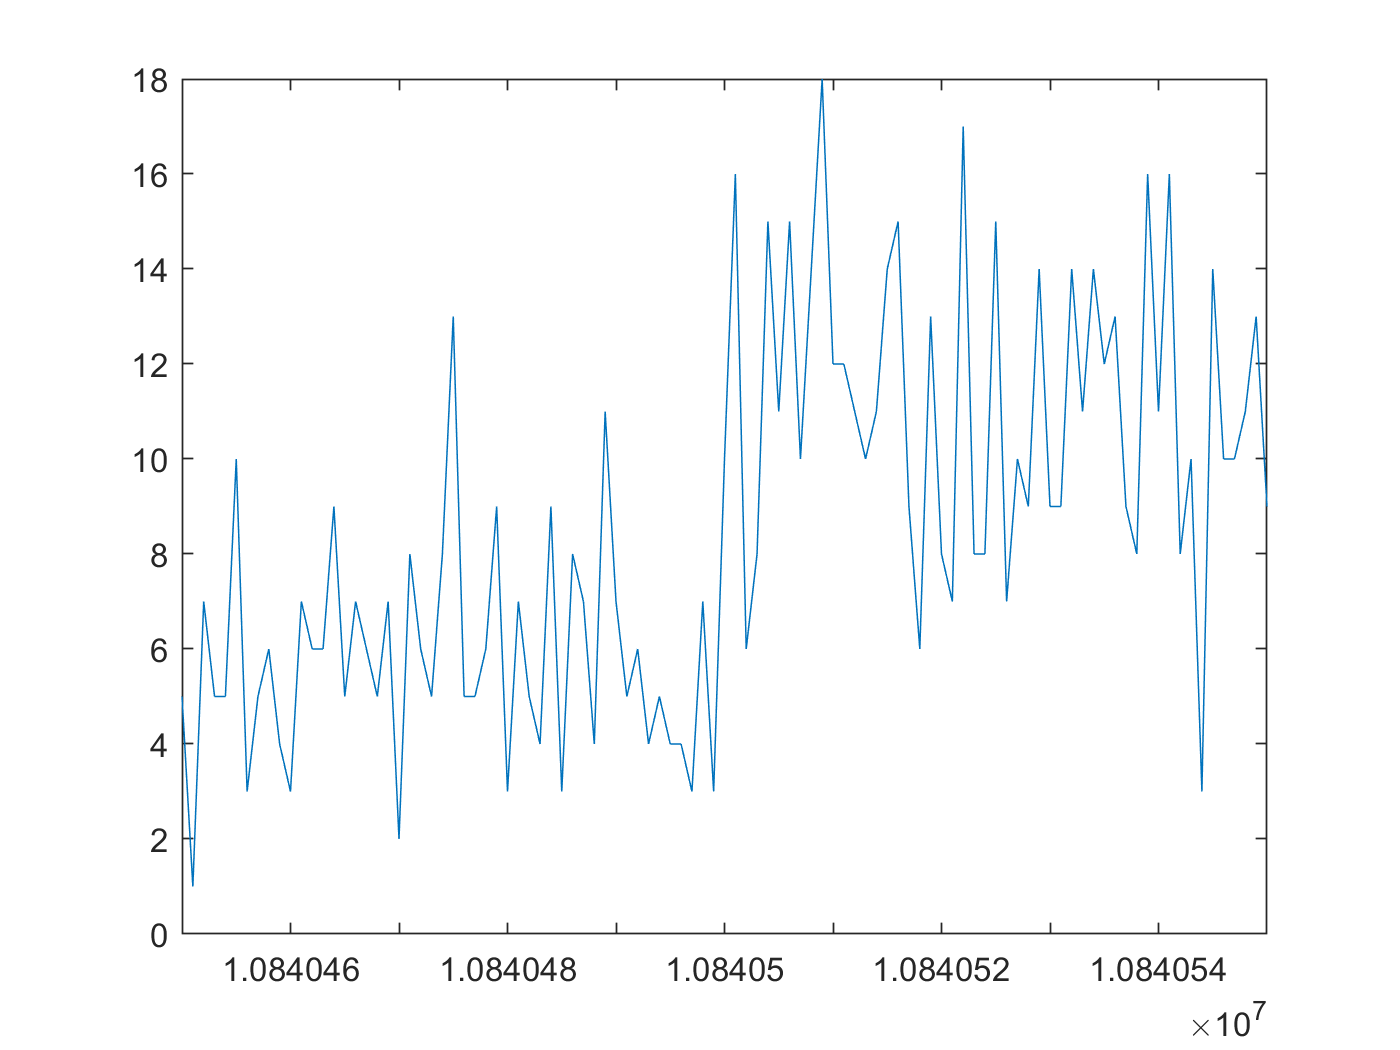

testrange1 = 40460:40550; % first big shift in counts
testrange2 = 94450:94550; % second big shift in counts
testrangeend = (54000*200+40450):(54000*200+40550); % stays the same at larger times
plot(testrangeend,mydata(testrangeend,4));

% each big section is a 90 minute orbital period
% 40500ish first big shift
mydata(40501+54000*12,2:4)

ans =   171.8057  315.0000   13.0000


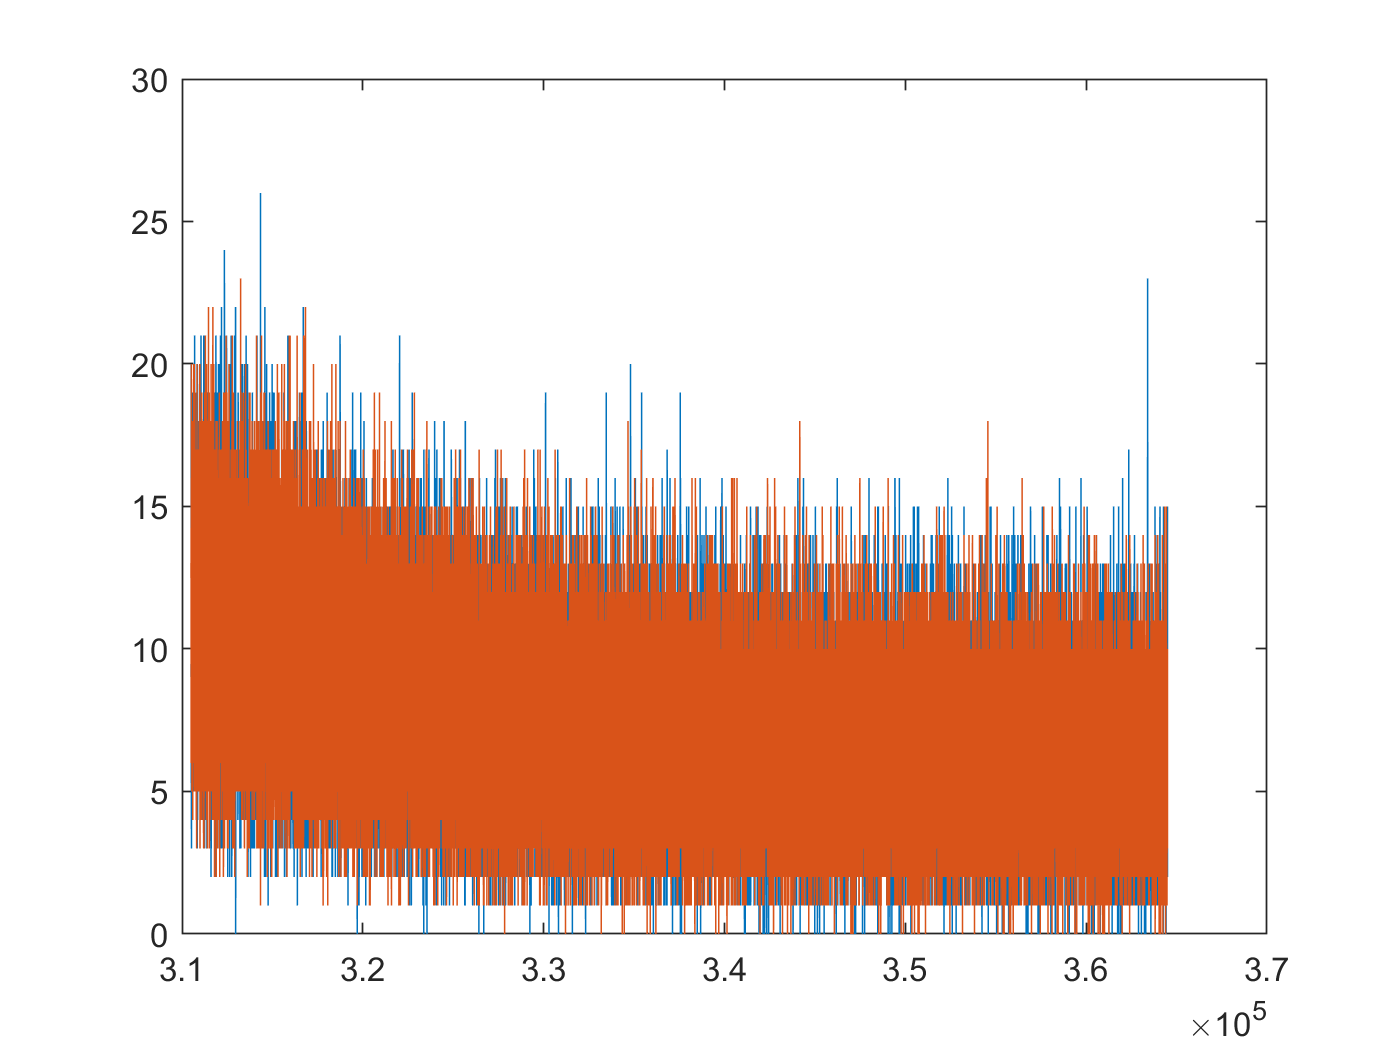

odddata1 = mydata(testrange1,1:4);
odddata2 = mydata(testrange2,1:4);

% Counts are going high when the Earth longitude hits 315 deg! Or else
% there is a gamma ray burst every 90 minutes? Unlikely.
% Could be resetting instruments?

indices = find(mydata(:,3)==315);
% diff(mydata(indices,2)) each set the solar phase moves 24.0632 degrees
range1 = indices(6):indices(7);
range2 = indices(13):indices(14);
plot(range1,mydata(range1,4));
hold on;
plot(range1,mydata(range2,4));
hold off;

% testpdf = (mydata(range1,4) + mydata(range2,4))/2;
% plot(1:length(testpdf),testpdf);

2) Background is not consistent. Average count appears to drop over 90 minute intervals starting at the 315 deg orbital longitude.

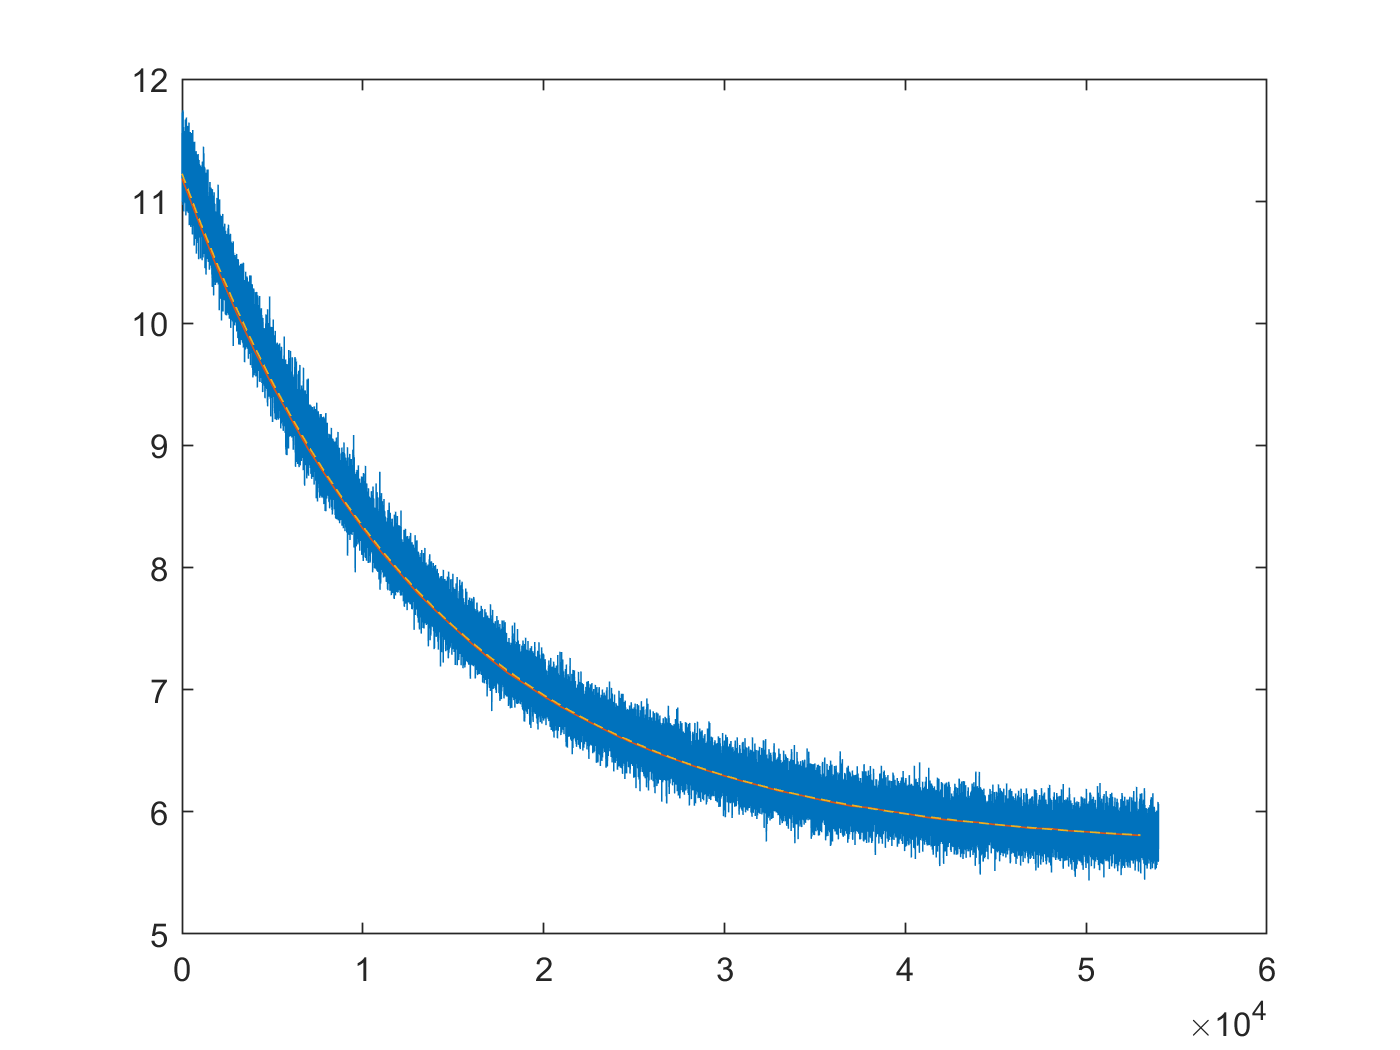

averagedata = mydata(indices(1):(indices(2))-1,4);
after315sample = mydata(indices(1):(indices(1)+0),4);
after315sample2 = mydata(indices(1)+10*60*60,4);

for k = 2:(length(indices)-1)
    averagedata = averagedata + mydata(indices(k):(indices(k+1))-1,4);
    after315sample = [after315sample;mydata(indices(k):(indices(k)+0),4)]; % first part of data
    after315sample2 = [after315sample2;mydata(indices(k)+10*60*60,4)];
end
averagedata = averagedata / k;

plot(1:length(averagedata),averagedata);
hold on;
% something about trial factors
% Compared to earlier samples, seems to be averaged OK.
% plot(1:length(after315sample),after315sample); % plot of after 315
% points, not clear what is going on.

bininterval = 0.1*10^4;
cruncheddata = [];
for j = 0:53
    cruncheddata = [cruncheddata,mean(averagedata((1+j*1000):((1+j)*1000)-1,1))];
end
crunchx = 1:bininterval:length(cruncheddata)*bininterval;
plot(crunchx,cruncheddata);
% hold on;
fun = @(t) 5.551*exp(-7.362e-05*t) + 5.675*exp(7.629e-08*t); % equation for time dependence
ytest = fun(crunchx);
plot(crunchx,ytest,'LineStyle','--');
hold off;

3) The time dependence for the mean rate is found by averaging short intervals of the counts from each 90 minute period and fitting an exponential decay curve. This curve function allows us to conjure the mean rate parameter needed to create the background model at a time within the 90 minute interval. Some sample histograms with Poisson PDFs generated this way to demonstrate:

histogram(after315sample,"Normalization","pdf");
fun(1)

ans = 11.2256

mean(after315sample)

ans = 11.1837

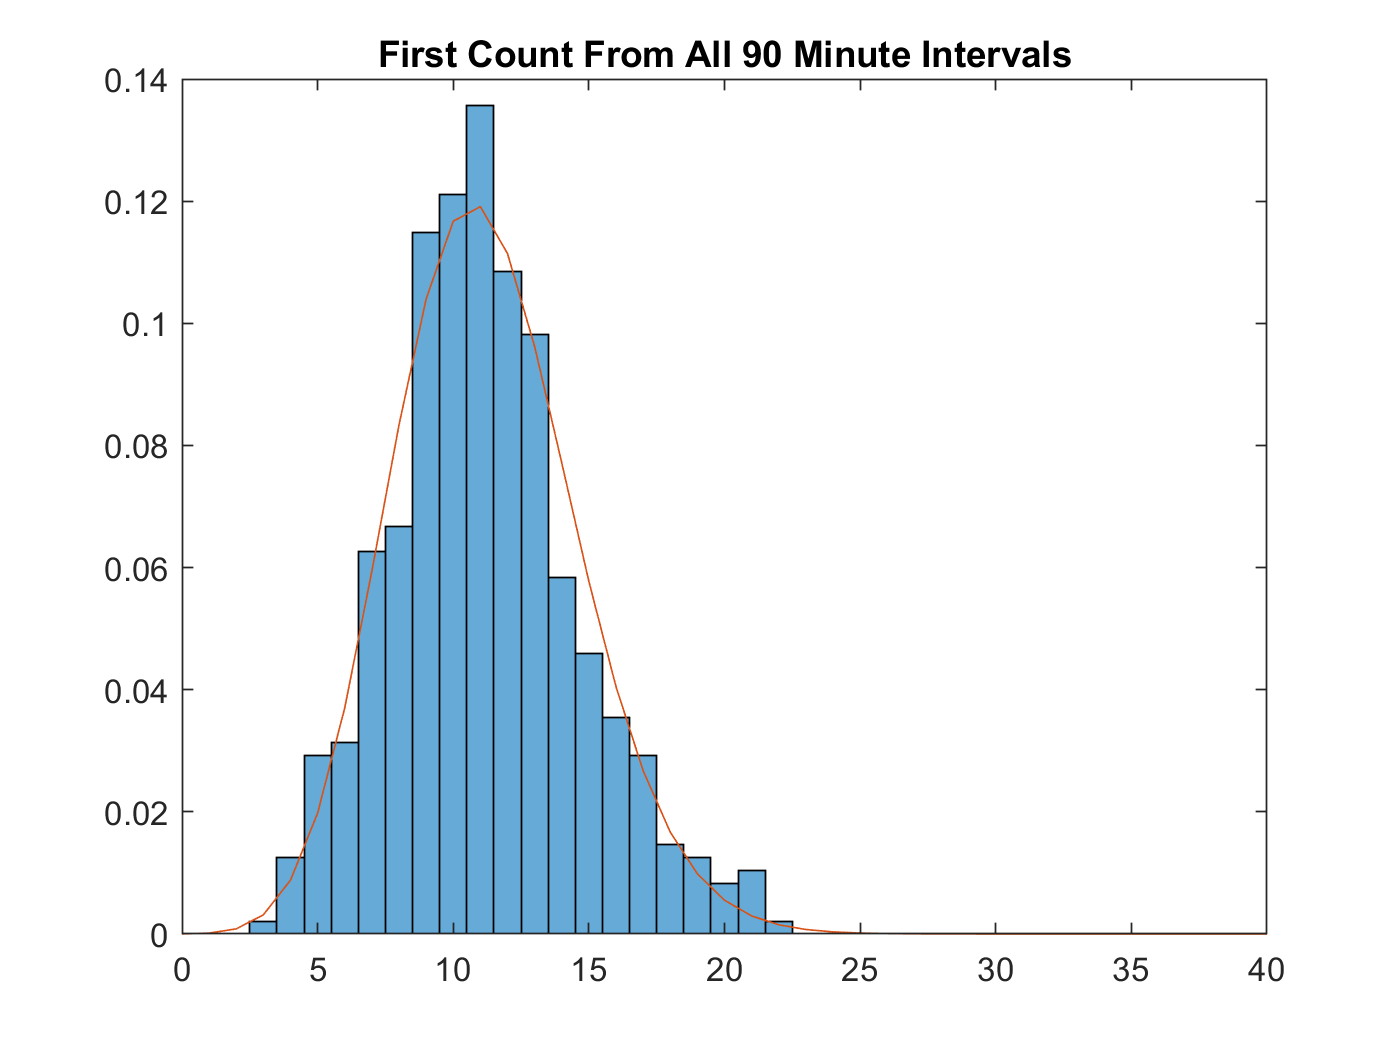

testdist = makedist("Poisson","lambda",fun(1));
mydist = pdf(testdist,0:40);
hold on;
plot(0:40,mydist);
title("First Count From All 90 Minute Intervals");
hold off;


histogram(after315sample2,"Normalization","pdf");
title("10*60*60 Count From All 90 Minute Intervals");
fun(10*60*60)

ans = 6.0827

mean(after315sample2)

ans = 6.1921

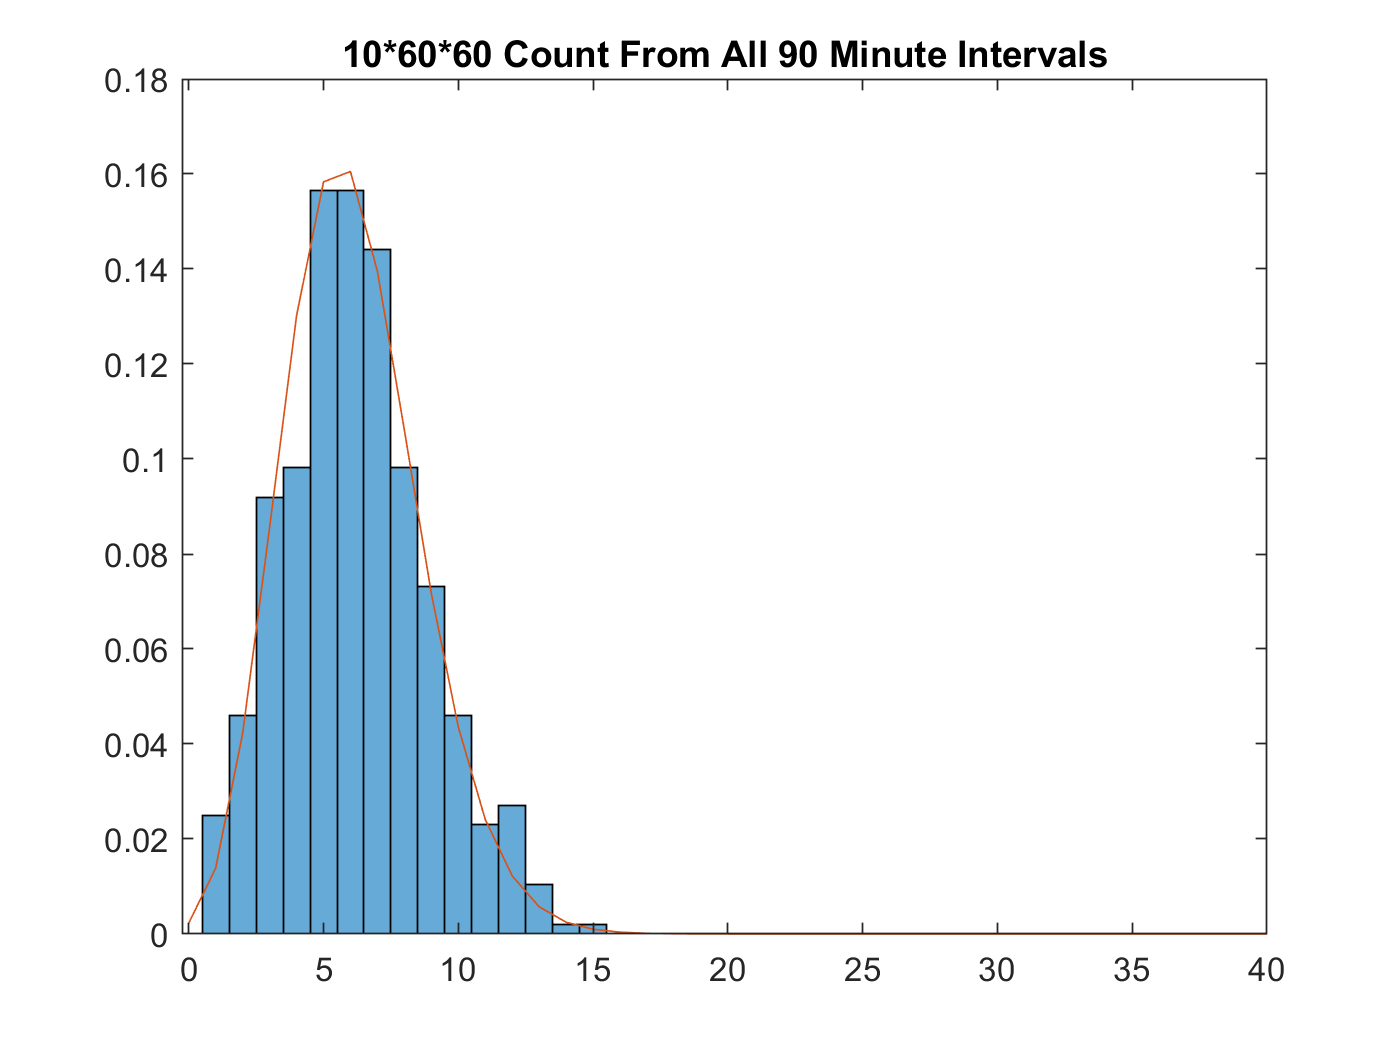

testdist2 = makedist("Poisson","lambda",fun(10*60*60));
mydist2 = pdf(testdist2,0:40);
hold on;
plot(0:40,mydist2);
hold off;

It could be a little better, the mean is not perfect. Smaller binning intervals may produce better results but may make fitting more of a challenge.

4) A varying background results in different thresholds for discovery sensitivity. For backgrounds early in the 90 minute interval the mean rate is larger, meaning both the mean and the standard deviation (width, square root of mean) is larger. The '5 sigma' threshold for 100 millisecond gamma ray bursts is larger for earlier times than it is for later ones in this 90 minute orbital period.

% TEST CODE: looking for solar phase angle influence

% Solar gamma rays never reach us. Shouldn't be a contributin factor.
% plot(mydata(xrange,1),mydata(xrange,2)); % solar phase repeatedly counts up linearly to 360 then drops to 0
%solarzeroes = find(mydata(:,2) < 0.008); % solar phase is very often decimal valued!
%mydata(6329:6468,2); % first low set (under 1)
%diff(solarzeroes); % about 50616 or 50617 between zeroes for solar phase
%histogram(mydata(6329:6329+50616,4)); % counts over solar phase range
%length(6329:56945)
%length(1:50616)
%plot(1:50616,mydata(1+6329:6329+50616,4)); 

% plot(mydata(xrange,1),mydata(xrange,3)); % as does longitude reading, circling east-west
%longzeroes = find(mydata(:,3) == 0);
%diff(longzeroes); % 54000 between zeroes for longitude
% this is what we expect from 10*60*90 = 54000
%histogram(mydata(47251:101251,4));
%plot(47251:101251,mydata(47251:101251,4));
% 94642 break, shifts up around here
% histogram(mydata(:,4)); % this one gives a nice enough distribution

Optional: thoughts are that this is something caused by the satellite and not a physical phenomena  of space producing a significant GRB every 90 minutes. Could be resetting? Double counting?

## Problem 2

1) Downloading data. 10 square 200 pixel images in 10x200x200 array.

clc; clear; close all;
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata2 = h5read("images.h5",'/imagestack');
mydata2(1,:)

ans =    -0.5049    0.3135    0.7735   -0.8526    0.3117    0.2109    0.8710    1.1809   -0.2430   -1.2276   -0.2997    1.5025    1.3085    0.2758   -0.0513    0.0964   -0.0627   -0.2774   -0.0143    0.9726    0.3614    0.5823    0.3794    0.7859    0.3061    1.0566    0.1774   -0.1467   -0.0073   -0.4464    1.0458   -0.7855    0.4475   -0.4512   -0.7697   -0.7025   -0.3926    0.6991   -0.2304   -0.3825   -0.5910   -0.2316   -0.3931   -0.5077    0.1902    0.2240    0.5676    0.1382    0.6729   -0.8276


2) Exploring the data.

oneimage = squeeze(mydata2(1,:,:));
max(max(oneimage))

ans = 46.0118

min(min(oneimage))

ans = -2.2839

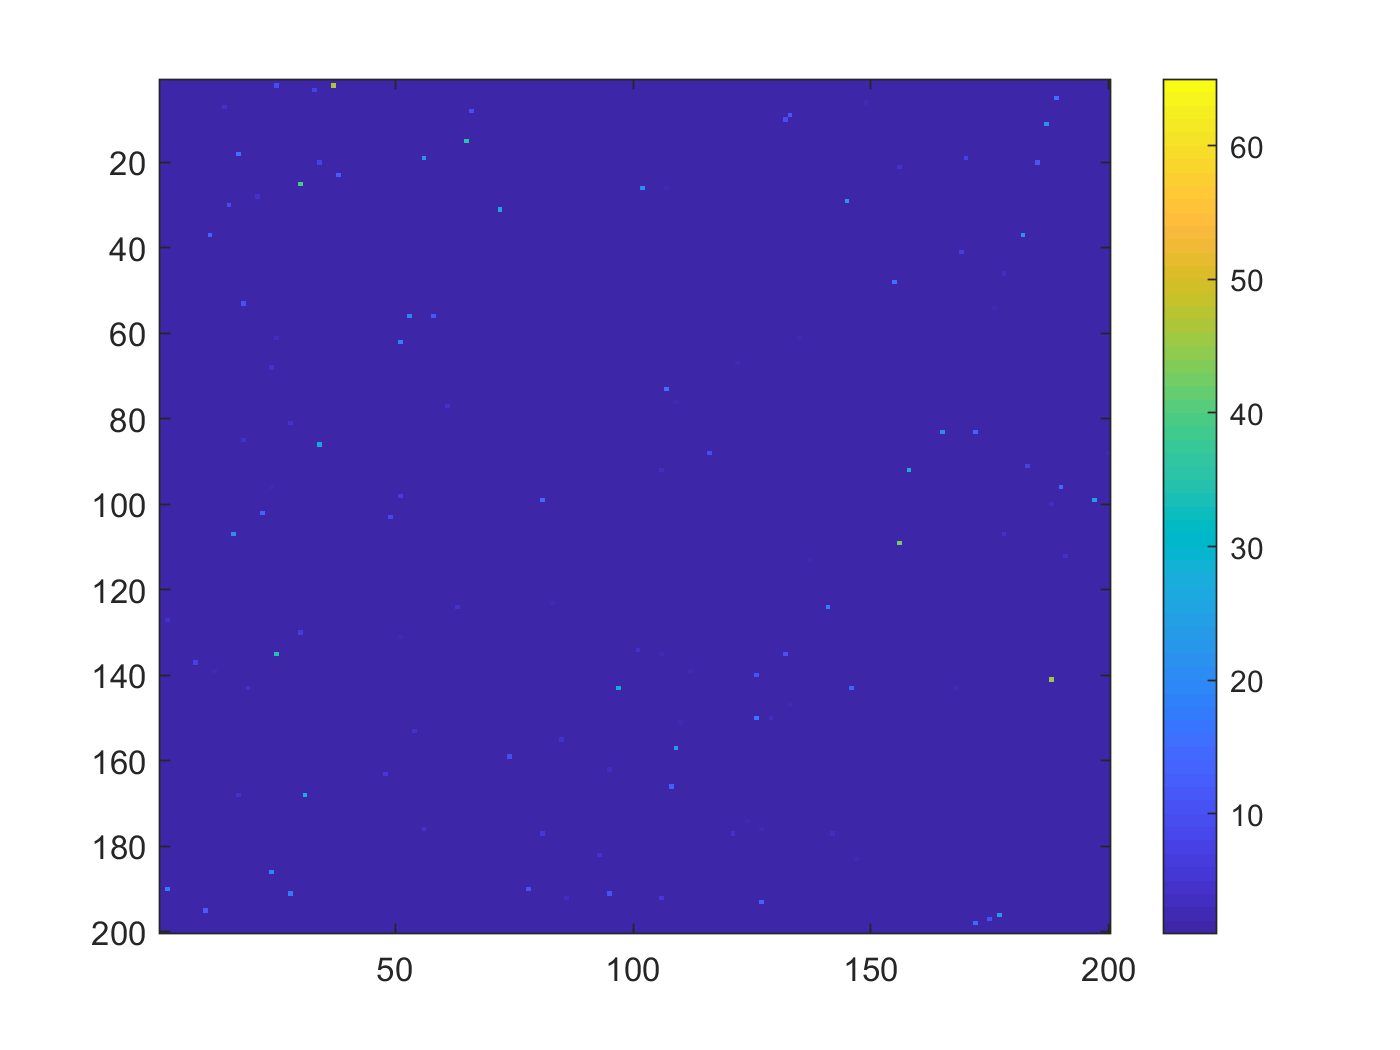

image(oneimage)
hold on;
colorbar
hold off;

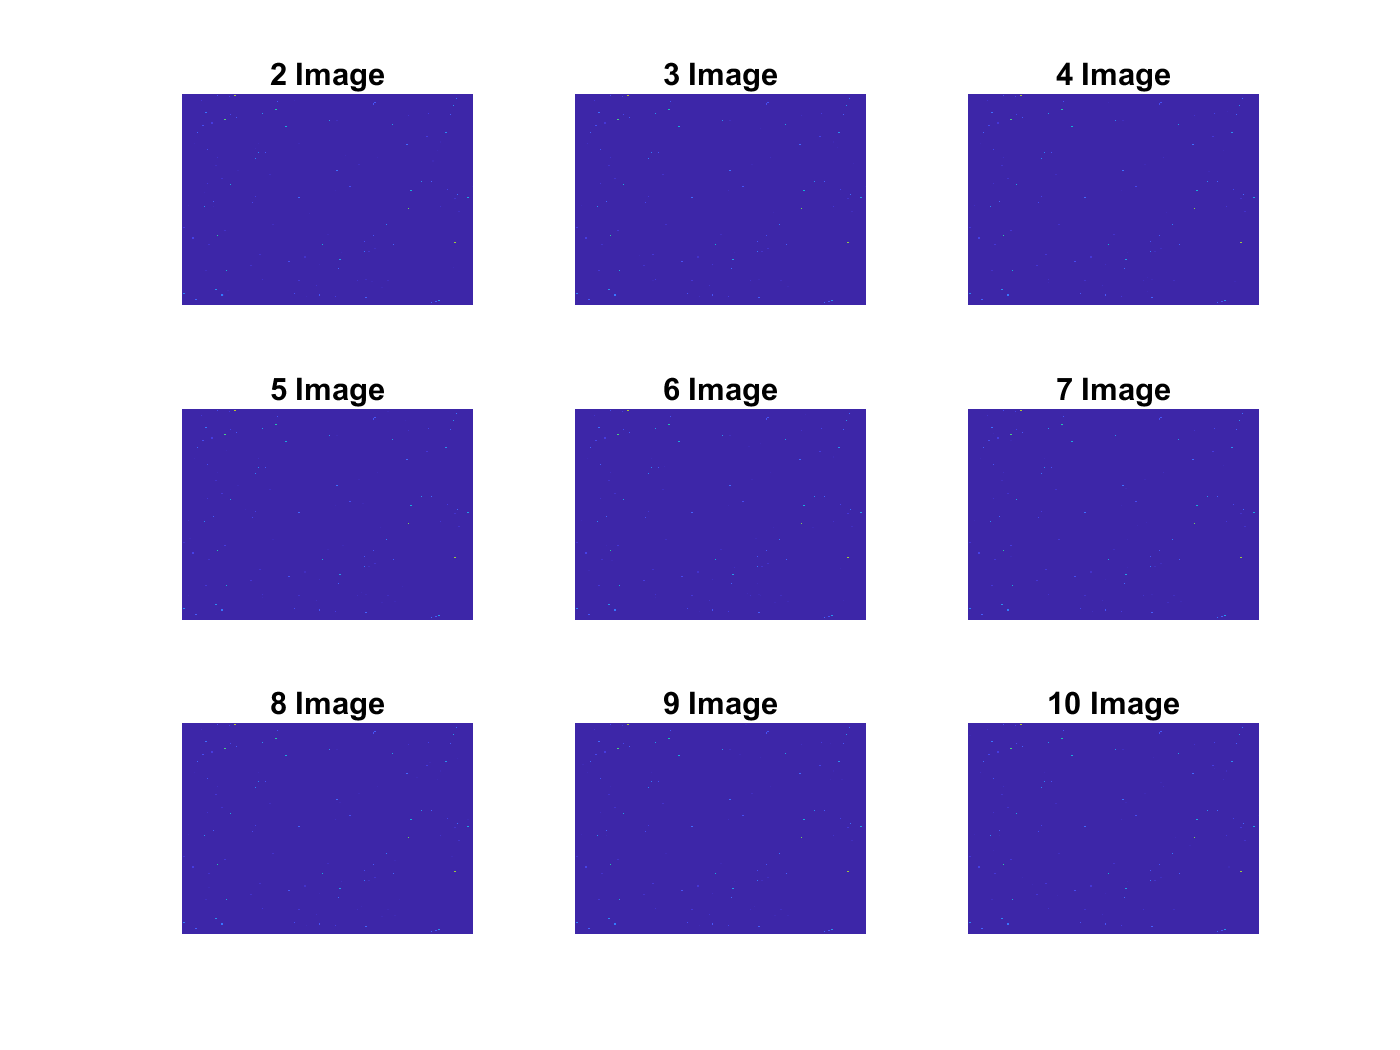


for k = 2:10
    oneimage = squeeze(mydata2(k,:,:));
    subplot(3,3,k-1);
    %max(max(oneimage))
    %min(min(oneimage))
    image(oneimage)
    axis off;
    % colorbar
    title(k + " Image");
end

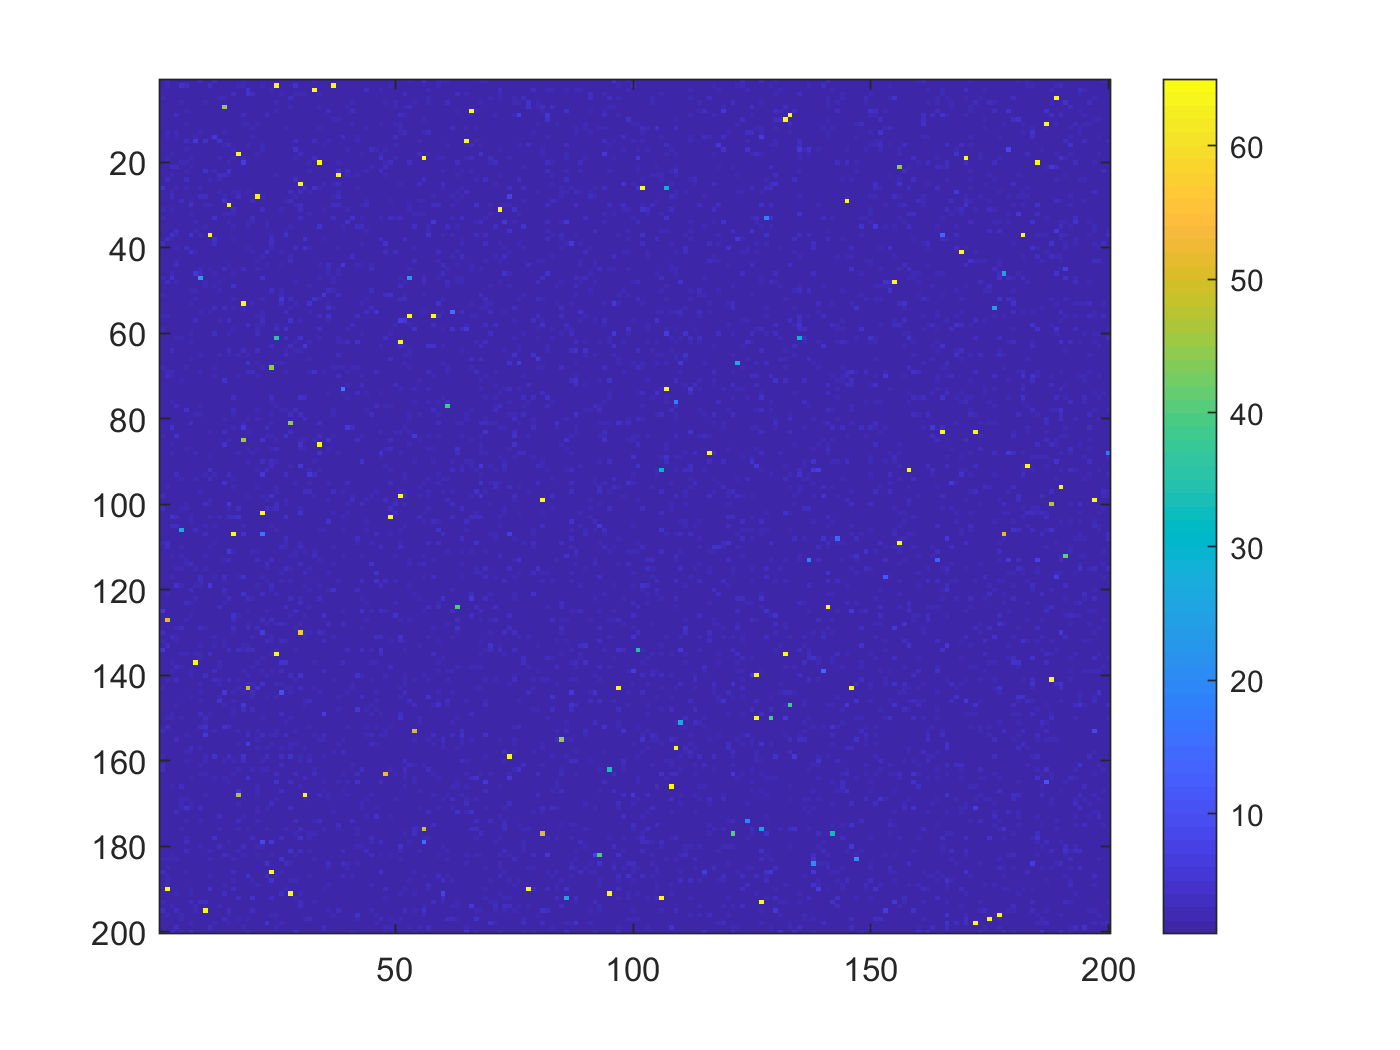

% faint star search
% faint stars will be consistently low and probably not vary significantly
% between images. random background fluctuations should smooth out?
close all hidden;
sumimg = zeros(200);
for k = 1:10
    sumimg = sumimg + squeeze(mydata2(k,:,:));
end
image(sumimg)
colorbar

% try getting a background from dark spots?

% takes awhile to run.
backgrounddata = [];
for k = 1:200
    for j = 1:200
        if sumimg(k,j) < 1
            backgrounddata = [backgrounddata; squeeze(mydata2(:,k,j))];
        end
    end
end

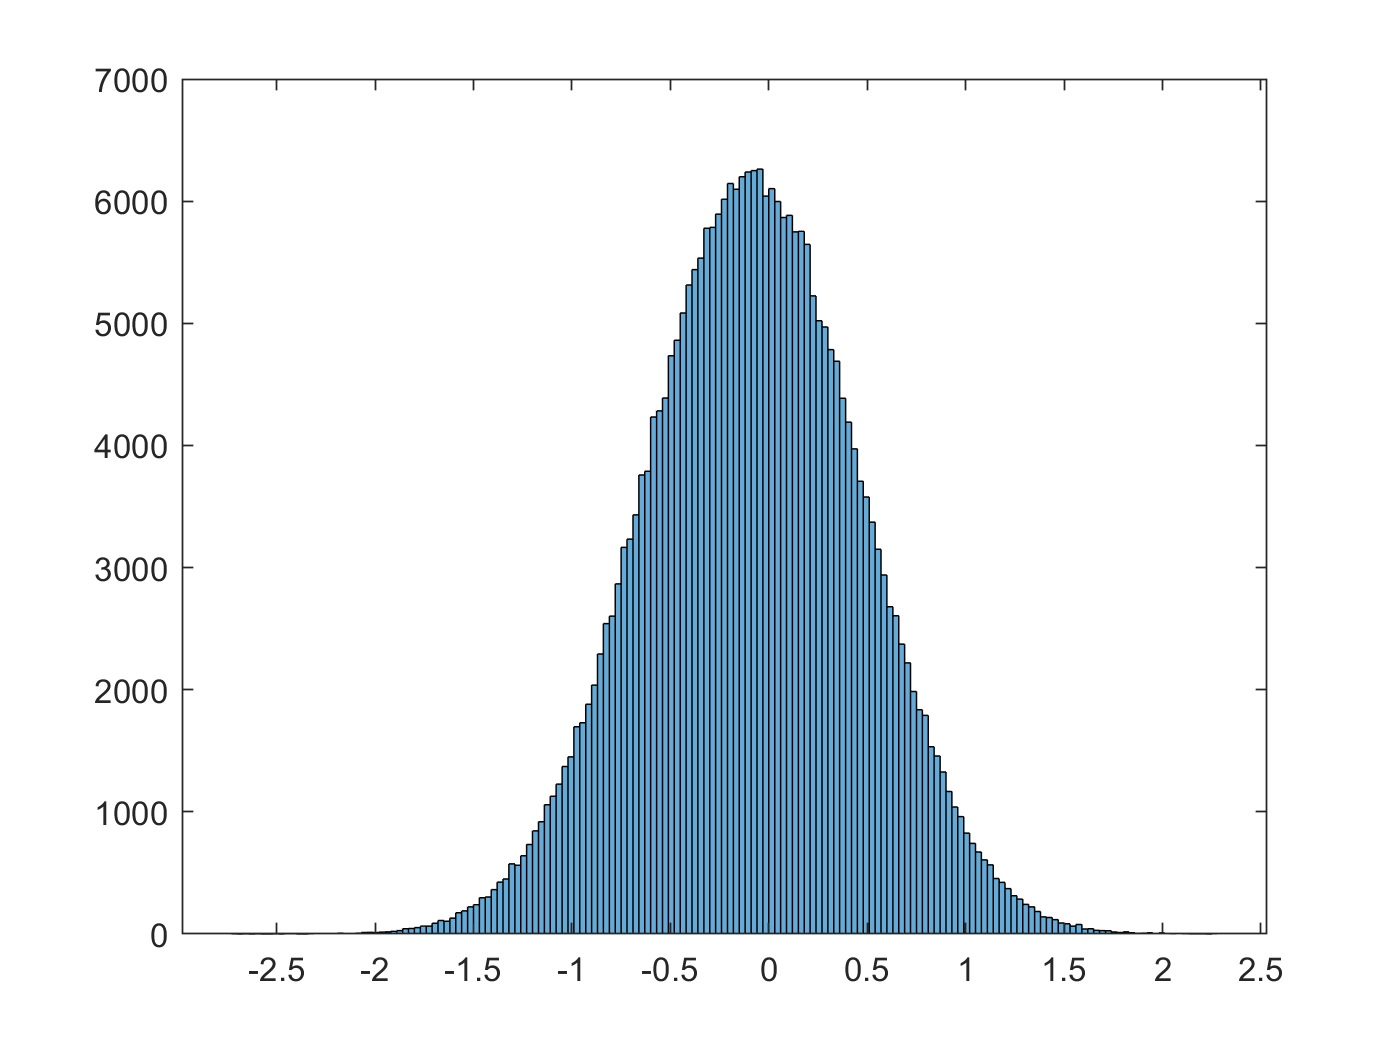

histogram(backgrounddata);

mean(backgrounddata)

ans = -0.0850


% removing high values
% for l = 1:10
%     for k = 1:200
%         for j = 1:200
%             singlepixeldata = squeeze(mydata2(l,k,j));
%             maxdiff(k,j) = max(singlepixeldata) - min(singlepixeldata);
%         end
%     end
% end

% trying to get a feel for how pixel values vary
singlepixeldata = squeeze(mydata2(:,1,1));
maxdiff = zeros(200);
max(singlepixeldata) - min(singlepixeldata)

ans = 1.9184

for k = 1:200
    for j = 1:200
        singlepixeldata = squeeze(mydata2(:,k,j));
        maxdiff(k,j) = max(singlepixeldata) - min(singlepixeldata);
    end
end
max(max(maxdiff))

ans = 4.1681

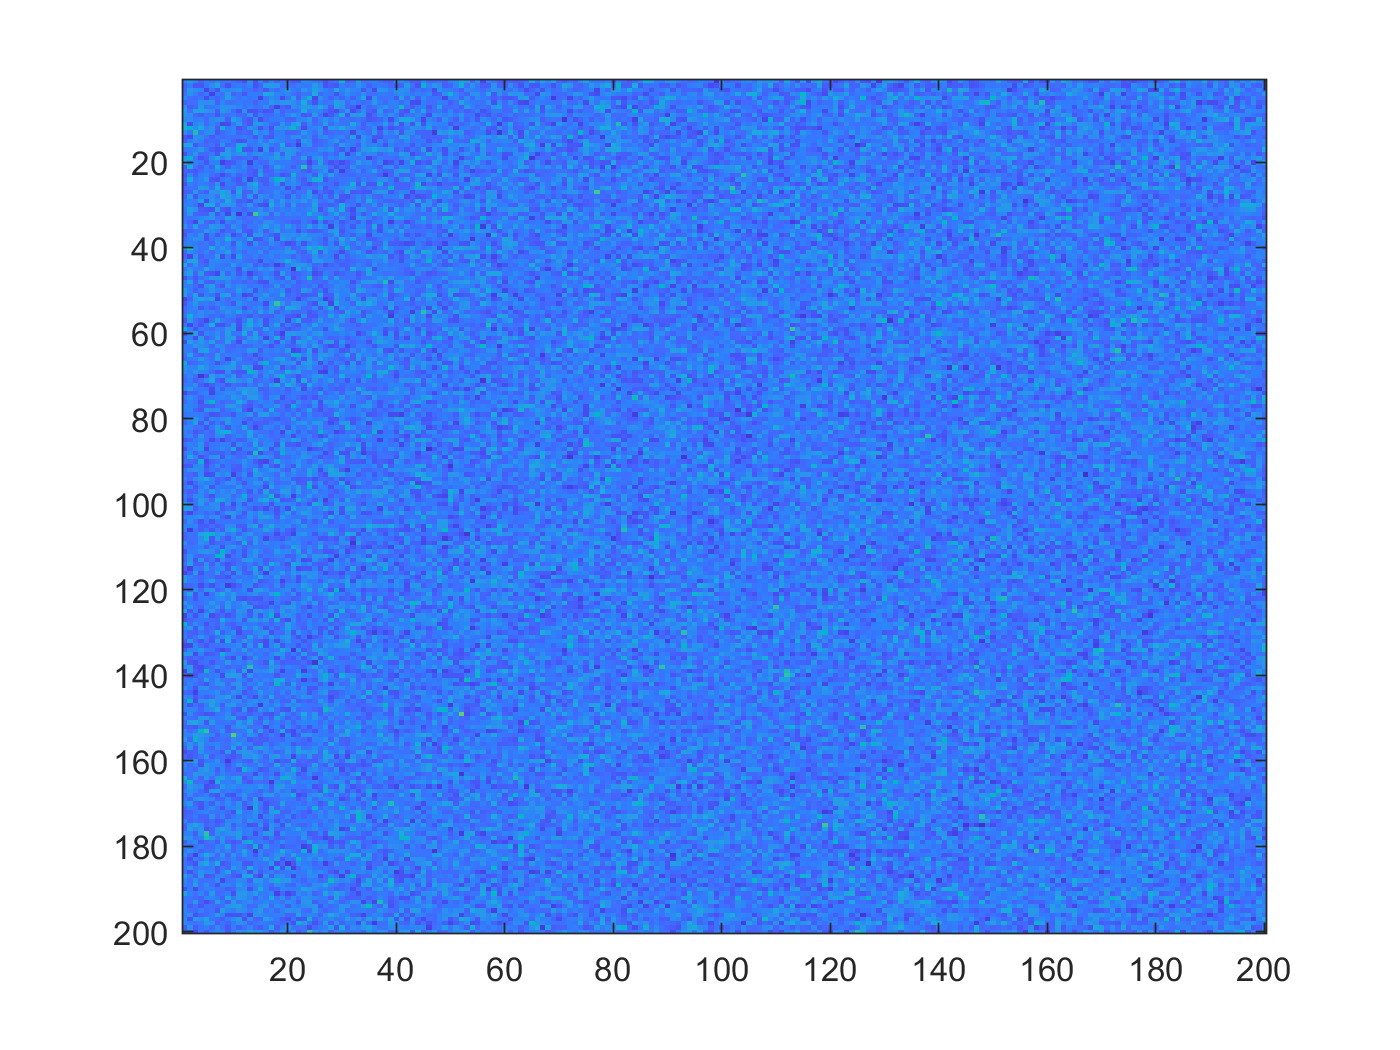

image(maxdiff.*10)